# Explore:   Single Tower with **Stationary** Ground 

Let's explore a single floor tower with a Stationary ground ... and with a Horizontal force applied to the FLOOR

## 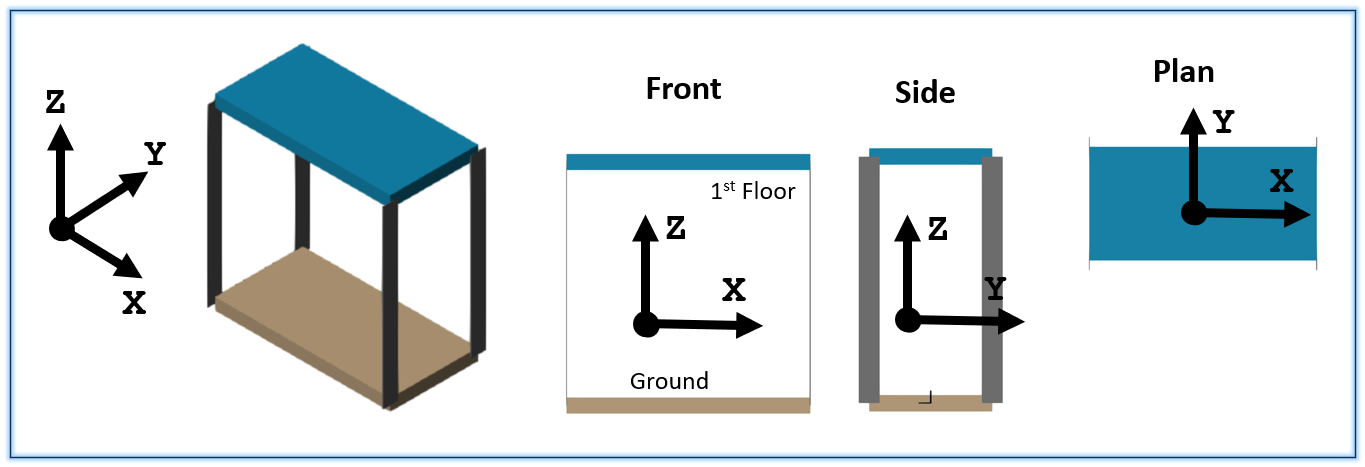

## Clear the workspace

clear

## Define the columns

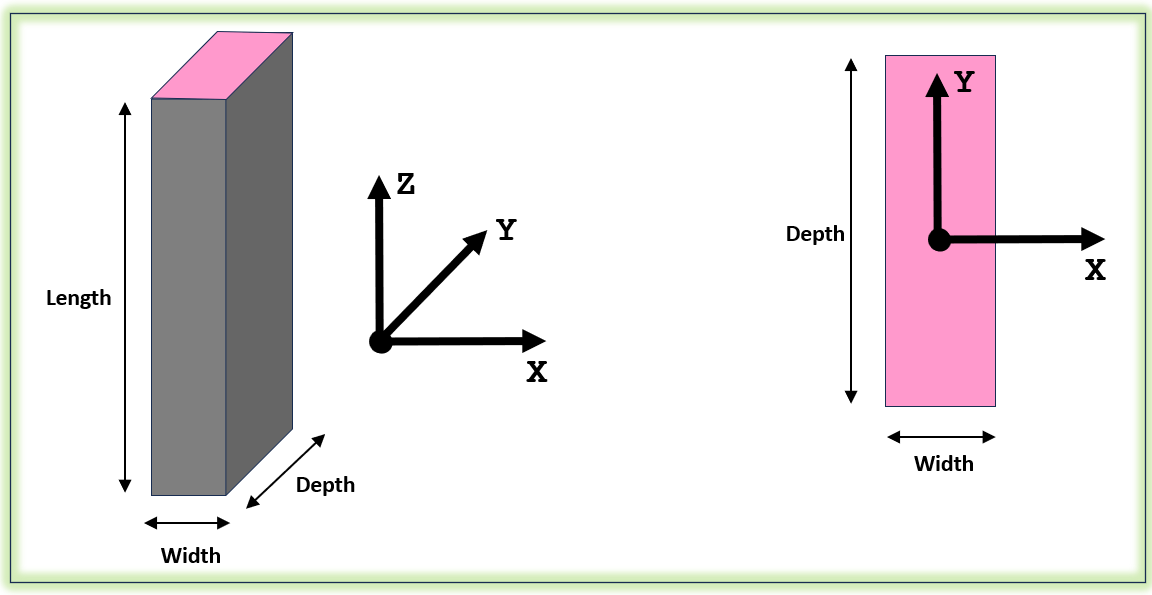

% col_OBJ  = bh_create_column_OBJ( Width=0.6/1000, ...
%                                  Depth=17.5/1000, ...
%                                  Length=150/1000, ...
%                                  density=7800);
col_OBJ  = bh_create_column_OBJ( Width=0.6/1000, ...
                                 Depth=10/1000, ...
                                 Length=150/1000, ...
                                 density=7800);
col_OBJ.num_eles      = 1;

Define Rayleigh damping coefficients

col_OBJ.damp_K_coeff  = 2*1e-2; % for static deflection test
% col_OBJ.damp_K_coeff  = 2*1e-4; % for resonance test  

So what have we got

col_OBJ

col_OBJ =   bh_flex_column_CLS with properties:

          WIDTH_x: 6.0000e-04
          DEPTH_y: 0.0100
         LENGTH_z: 0.1500
          density: 7800
      E_GPa_Young: 200
        v_Poisson: 0.3000
     damp_M_coeff: 0
     damp_K_coeff: 0.0200
         num_eles: 1
    num_ret_modes: 5
          BC_case: "FIXED_FIXED_WITH_SWAY"
             mass: 0.0070
              vol: 9.0000e-07
               Ix: 5.0000e-11
               Iy: 1.8000e-13
               Kx: 128


## Define the floors

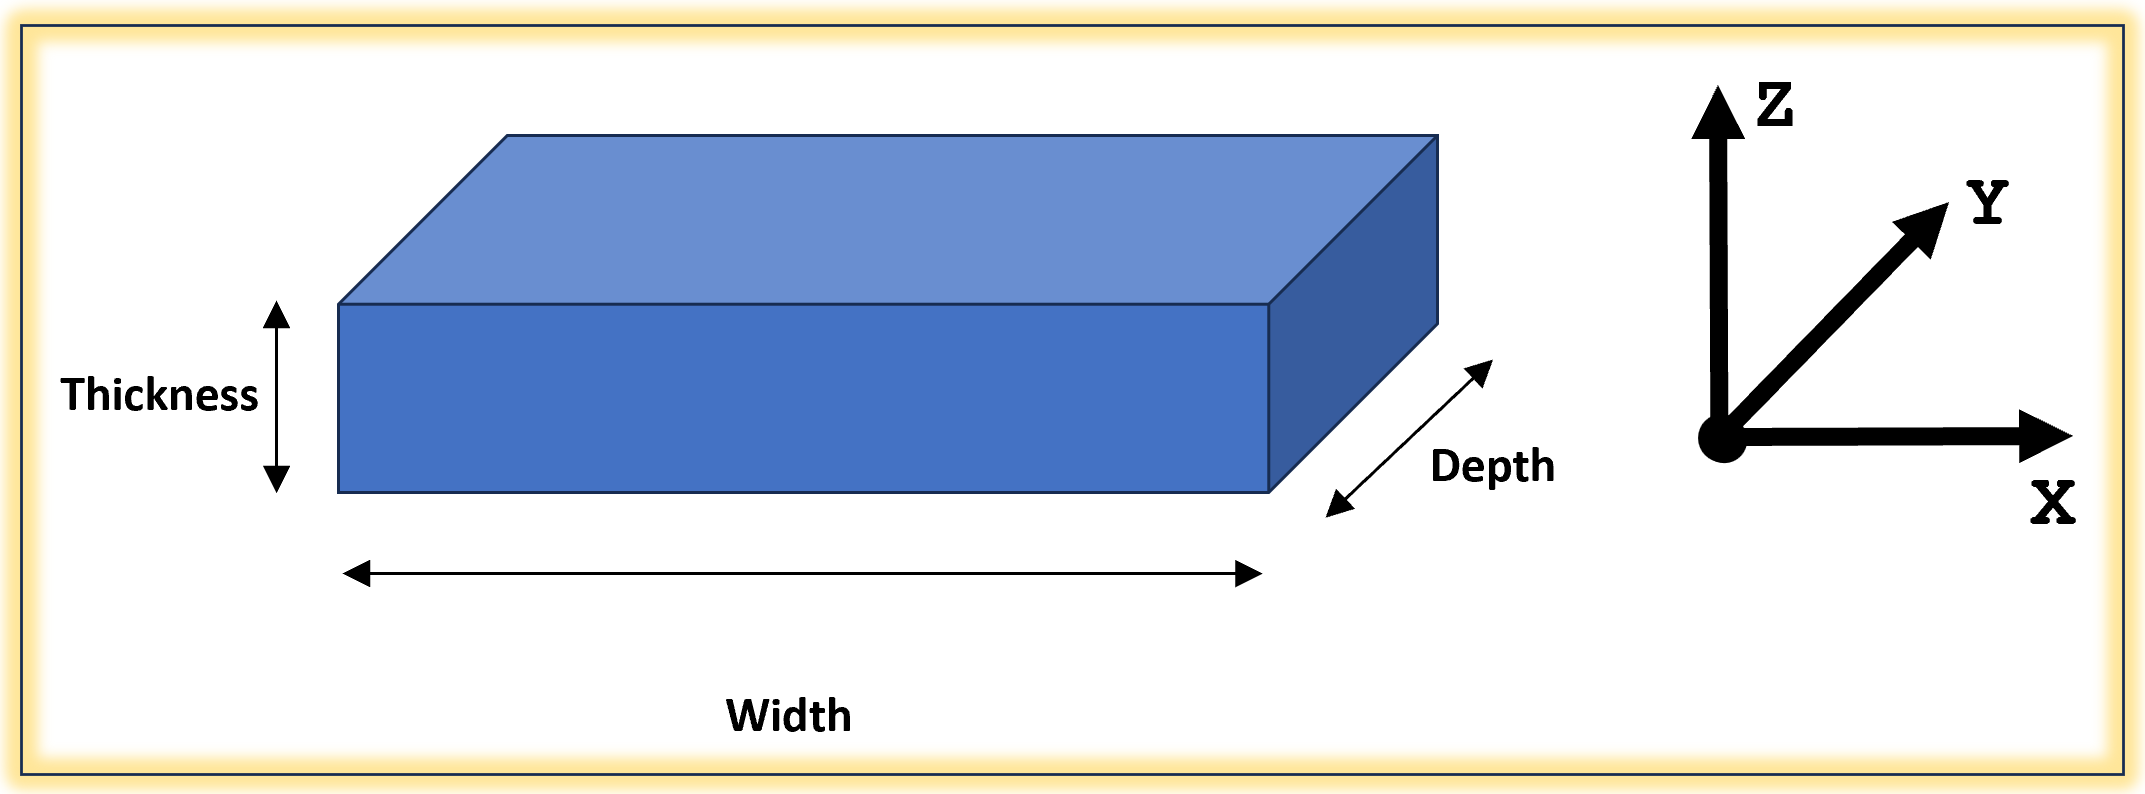

floor_OBJ = bh_create_floor_OBJ( Width=30/100, ...
                                 Depth=15/100, ...
                                 Thickness=2/100, ...
                                 Mass=0.5 )

floor_OBJ =   bh_solid_floor_CLS with properties:

        WIDTH: 0.3000
        DEPTH: 0.1500
    THICKNESS: 0.0200
         MASS: 0.5000


## Calculate the expected deflection of 1st floor

F_applied = 5; % (N)

Boundary Condition:  Fixed-Fixed (Sideways sway)

col_OBJ.BC_case = "FIXED_FIXED_WITH_SWAY";
col_OBJ.Kx

ans = 128

disp            = F_applied / (4 * col_OBJ.Kx)

disp = 0.0098

Boundary Condition:  Cantilever

col_OBJ.BC_case = "CANTILEVER";
col_OBJ.Kx

ans = 32

disp            = F_applied / (4 * col_OBJ.Kx)

disp = 0.0391

## Now compare against the Simulink model

% open_system("bh_single_tower_STATIC_compare_BCs.slx")